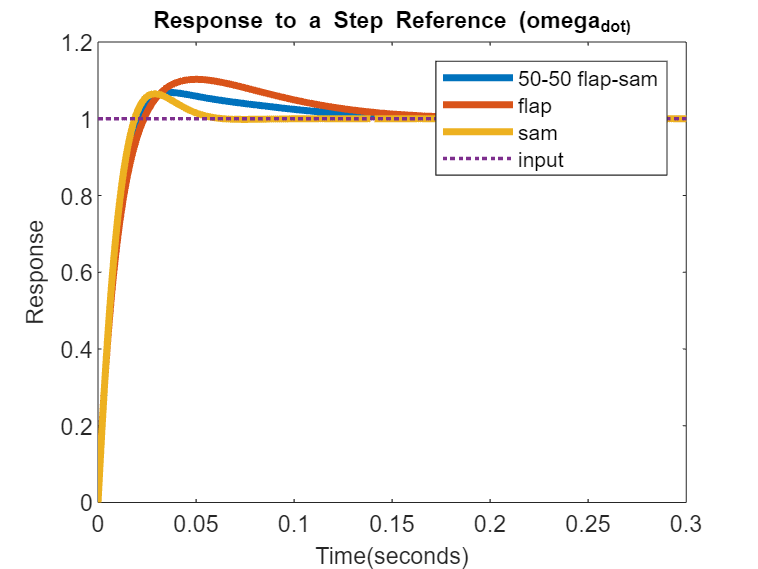

clc
clear all
close all
load disturbance_pure_flap.mat 
load disturbance_pure_sam.mat
load disturbance_half_flap.mat
load disturbance_half_sam.mat
load step_pure_flap.mat
load step_pure_sam.mat
load step_half_flap.mat
load step_half_sam.mat

linesize = 3;
Fontsize = 10;

dt = 0:0.001:0.3;
s_dt = size(dt);
s_dt = s_dt(1,2);
desired_step = ones(1,s_dt);

plot (dt,step_half_flap+step_half_sam,'LineWidth',linesize)
hold on
plot (dt,step_pure_flap,'LineWidth',linesize)
plot (dt,step_pure_sam,'LineWidth',linesize) 
plot (dt,desired_step,'lineStyle',':','LineWidth',linesize/2) 
hold off
ylabel('Response','FontSize',Fontsize)
xlabel('Time(seconds)','FontSize',Fontsize)
title('Response to a Step Reference (omega_dot)','FontSize',Fontsize)
legend('50-50 flap-sam','flap','sam','input')

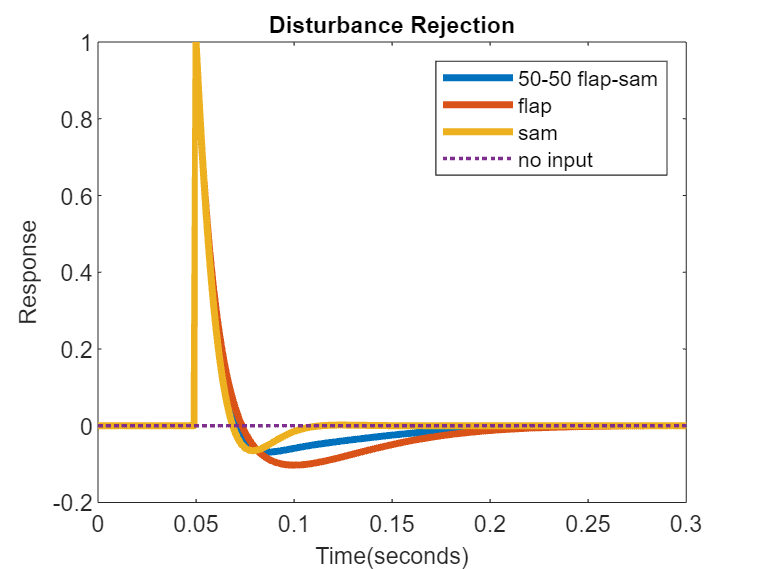


desired_step = zeros(1,s_dt);
plot (dt,disturbance_half_flap+disturbance_half_sam,'LineWidth',linesize)
hold on
plot (dt,disturbance_pure_flap,'LineWidth',linesize)
plot (dt,disturbance_pure_sam,'LineWidth',linesize) 
plot (dt,desired_step,'lineStyle',':','LineWidth',linesize/2) 
hold off
ylabel('Response','FontSize',Fontsize)
xlabel('Time(seconds)','FontSize',Fontsize)
title('Disturbance Rejection','FontSize',Fontsize)
legend('50-50 flap-sam','flap','sam','no input')

%angle = 0:deg2rad(-1):4*pi;
clc
clear all
close all

% waypoints
angle = 0:deg2rad(-1):-4*pi; % go from right to left, cw rotation from monocopter
a = 0.25;
b = a+0.15;
x = ((a*angle) - b*sin(angle))+4; 
y = (a - b*cos(angle))+2.5; 

% bottom trochoid
bx = -x+4.85; 
by = -y+4.7;

% sideways trochoid
sy = -x+4.85; 
sx = -y+4.7;

% time per setpt
hz = 60; % default used to be 300
time_per_setpt = 1/hz;

% yaw rate for waypoints 
s_x = size(x);
d_x = zeros(1,s_x(:,2)-1);
d_y = zeros(1,s_x(:,2)-1);
d_bx = zeros(1,s_x(:,2)-1);
d_by = zeros(1,s_x(:,2)-1);

for i = 2:s_x(:,2)
    d_x(1,i-1) = x(:,i) - x(:,i-1); 
    d_y(1,i-1) = y(:,i) - y(:,i-1); 
    d_bx(1,i-1) = bx(:,i) - bx(:,i-1); 
    d_by(1,i-1) = by(:,i) - by(:,i-1);  
end

direction = atan2(d_y,d_x); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
direction_deg = rad2deg(direction);

b_direction = atan2(d_by,d_bx); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
b_direction_deg = rad2deg(b_direction);

diff_rad = zeros(1,s_x(:,2)-2);
diff_deg = zeros(1,s_x(:,2)-2);

b_diff_rad = zeros(1,s_x(:,2)-2);
b_diff_deg = zeros(1,s_x(:,2)-2);

for i = 2:s_x(:,2)-1
    diff_rad(1,i-1) = (direction(1,i) - direction(1,i-1))/(time_per_setpt);
    diff_deg(1,i-1) = (direction_deg(1,i) - direction_deg(1,i-1))/(time_per_setpt);
    b_diff_rad(1,i-1) = (b_direction(1,i) - b_direction(1,i-1))/(time_per_setpt);
    b_diff_deg(1,i-1) = (b_direction_deg(1,i) - b_direction_deg(1,i-1))/(time_per_setpt);
end

threshold = [1 99];
diff_deg = (rmoutliers(diff_deg(1,:),"percentiles",threshold));
diff_deg_size = size(diff_deg);
b_diff_deg = (rmoutliers(b_diff_deg(1,:),"percentiles",threshold));
b_diff_deg_size = size(b_diff_deg);
%plot(bx, by)

% plot(x, y)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% axis equal
% title('one side trochoid')

% plot(sx, sy)
% hold on
% plot(x, y)
% hold off
% xlabel('X-Pose')
% ylabel('Y-Pose')
% axis equal
% title('trochoid')

plot(bx, by)
hold on
plot(x, y)
hold off
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
title('trochoid')

plot((1:diff_deg_size(1,2))/hz, diff_deg(1,1:7050))
hold on
plot((1:b_diff_deg_size(1,2))/hz, b_diff_deg(1,1:706))
hold off
xlabel('Time(s)')
ylabel('Yaw rate(Deg/s)')
xlim([0,12]);
% ylim([0,850]);
title('Yaw rate')

%%%%%% this one is without the side loops
%angle = 0:deg2rad(-1):4*pi;
clc
clear all
close all

% waypoints
angle = 0:deg2rad(-45):-4*pi; % go from right to left, cw rotation from monocopter
a = 0.25;
b = a+0.15;
x = ((a*angle) - b*sin(angle))+4; 
y = (a - b*cos(angle))+2.5; 
z = linspace(1.5,2.5,8);
inv_z = flip(z,2);
z = cat(2,z,inv_z(1,2:8));


inv_x = flip(x,2);
% bx = -x+4.85; 
% by = -y+4.7;

ext_x = [0.79,0.78];
ext_y = [2.4,2.25];

v = 16;
x = x(1,2:v)

x =     4.0865    4.0073    3.6938    3.2146    2.7354    2.4219    2.3427    2.4292    2.5157    2.4365    2.1230    1.6438    1.1646    0.8511    0.7719


y = y(1,2:v)

y =     2.4672    2.7500    3.0328    3.1500    3.0328    2.7500    2.4672    2.3500    2.4672    2.7500    3.0328    3.1500    3.0328    2.7500    2.4672



inv_x = inv_x(1,2:v)

inv_x =     0.7719    0.8511    1.1646    1.6438    2.1230    2.4365    2.5157    2.4292    2.3427    2.4219    2.7354    3.2146    3.6938    4.0073    4.0865


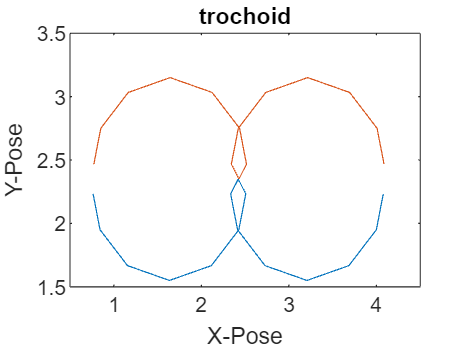


% x = cat(2,x,ext_x)
% y = cat(2,y,ext_y)

bx = -x+4.85; 
by = -y+4.7;
inv_bx = -inv_x+4.85; 

col = size(x);
col = col(1,2);

% time per setpt
% hz = 300;
% time_per_setpt = 1/hz;

% yaw rate for waypoints 
% s_x = size(x);
% d_x = zeros(1,s_x(:,2)-1);
% d_y = zeros(1,s_x(:,2)-1);
% d_bx = zeros(1,s_x(:,2)-1);
% d_by = zeros(1,s_x(:,2)-1);

% for i = 2:s_x(:,2)
%     d_x(1,i-1) = x(:,i) - x(:,i-1); 
%     d_y(1,i-1) = y(:,i) - y(:,i-1); 
%     d_bx(1,i-1) = bx(:,i) - bx(:,i-1); 
%     d_by(1,i-1) = by(:,i) - by(:,i-1);  
% end
% 
% direction = atan2(d_y,d_x); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
% direction_deg = rad2deg(direction);
% 
% b_direction = atan2(d_by,d_bx); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
% b_direction_deg = rad2deg(b_direction);
% 
% diff_rad = zeros(1,s_x(:,2)-2);
% diff_deg = zeros(1,s_x(:,2)-2);
% 
% b_diff_rad = zeros(1,s_x(:,2)-2);
% b_diff_deg = zeros(1,s_x(:,2)-2);
% 
% for i = 2:s_x(:,2)-1
%     diff_rad(1,i-1) = (direction(1,i) - direction(1,i-1))/(time_per_setpt);
%     diff_deg(1,i-1) = (direction_deg(1,i) - direction_deg(1,i-1))/(time_per_setpt);
%     b_diff_rad(1,i-1) = (b_direction(1,i) - b_direction(1,i-1))/(time_per_setpt);
%     b_diff_deg(1,i-1) = (b_direction_deg(1,i) - b_direction_deg(1,i-1))/(time_per_setpt);
% end
% 
% threshold = [1 99];
% diff_deg = (rmoutliers(diff_deg(1,:),"percentiles",threshold));
% b_diff_deg = (rmoutliers(b_diff_deg(1,:),"percentiles",threshold));

plot(bx,by)
% plot(inv_x,y)
hold on
%plot(inv_x,y)
plot(x,y)
hold off
xlabel('X-Pose')
ylabel('Y-Pose')
xlim([0.5,4.5])
title('trochoid')

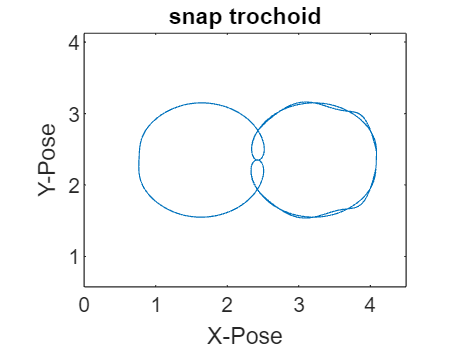


% plot(1:15, diff_deg(1,1:15))
% % hold on
% % plot(1:15, b_diff_deg(1,1:15))
% % hold off
% xlabel('Seq')
% ylabel('Yaw rate')
% % ylim([0,850]);
% title('Yaw rate')


% min snap
t_wpts_xy = [x bx x bx;y by y by]; % repeats for 4 times to ensure smoothness but we only take the middle points
% tpts = 0:5;

speed = 1;
r = 0.5;
omega = speed / r; % 1 m/s = 1 rad/s based on v = r*omega
% time_per_eigth = (pi/4)/speed; 
% sample_per_loop = 100;
% time_per_setpt = (time_per_eigth * 8) / sample_per_loop; 

time_per_seg = ((2*pi)/col)/omega; % 0.784
circle_tpts = 0:time_per_seg:time_per_seg*col*4; % intervals @ 1 m/s = 1 rad/s based on v = r*omega
circle_tpts = circle_tpts(1,1:col*4);
% hz = 100;
hz = 60; % default is 300
time_per_setpt = 1/hz;
sample_per_loop = (time_per_seg * col) / time_per_setpt;  % 2258
sample_per_loop = ceil(sample_per_loop);
laps = 2;
numsamples = sample_per_loop*2*laps;

[t_xy,t_xyd,t_xydd,t_xyddd,t_xydddd,t_xypp,t_xytimepoints,t_xytsamples] = minsnappolytraj(t_wpts_xy ,circle_tpts,numsamples);
t_final_pose = zeros(2,numsamples);
t_final_vel = zeros(2,numsamples);
t_final_acc = zeros(2,numsamples);
t_final_jerk = zeros(2,numsamples);
t_final_snap = zeros(2,numsamples);

for v = 1:2
    t_final_pose(v,:) = t_xy(v,:);
    t_final_vel(v,:) = t_xyd(v,:);
    t_final_acc(v,:) = t_xydd(v,:);
    t_final_jerk(v,:) = t_xyddd(v,:);
    t_final_snap(v,:) = t_xydddd(v,:);
end


plot(t_xy(1,:), t_xy(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
title('snap trochoid')


diff_pos = zeros(2,(numsamples));

for v = 1:2
    for i = 2:numsamples
        diff_pos(v,i) = t_final_pose(v,i) - t_final_pose(v,i-1); 
        % d_bx(1,i-1) = bx(:,i) - bx(:,i-1); 
        % d_by(1,i-1) = by(:,i) - by(:,i-1);  
    end
end

direction = atan2(diff_pos(2,:),diff_pos(1,:)); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
direction_deg = rad2deg(direction);

% b_direction = atan2(d_by,d_bx); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
% b_direction_deg = rad2deg(b_direction);

diff_rad = zeros(1,numsamples-2);
diff_deg = zeros(1,numsamples-2);

% b_diff_rad = zeros(1,sample_per_loop-2);
% b_diff_deg = zeros(1,sample_per_loop-2);

for i = 2:numsamples-1
    diff_rad(1,i-1) = (direction(1,i) - direction(1,i-1))/(time_per_setpt);
    diff_deg(1,i-1) = (direction_deg(1,i) - direction_deg(1,i-1))/(time_per_setpt);
    % b_diff_rad(1,i-1) = (b_direction(1,i) - b_direction(1,i-1))/(time_per_setpt);
    % b_diff_deg(1,i-1) = (b_direction_deg(1,i) - b_direction_deg(1,i-1))/(time_per_setpt);
end

threshold = [1 99];
diff_deg = (rmoutliers(diff_deg(1,:),"percentiles",threshold));
L = size(diff_deg);
xlim([0,4.5])

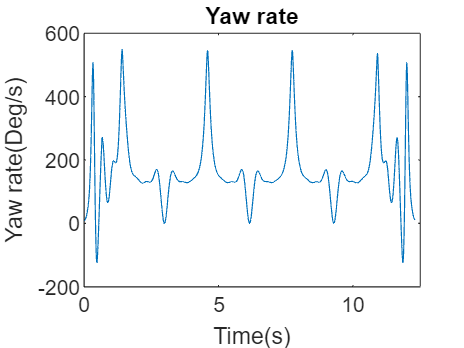

% b_diff_deg = (rmoutliers(b_diff_deg(1,:),"percentiles",threshold));

plot((1:L(1,2))/hz, diff_deg(1,1:L(1,2)))
% hold on
% plot(1:15, b_diff_deg(1,1:15))
% hold off
xlabel('Time(s)')
ylabel('Yaw rate(Deg/s)')
% ylim([0,850]);
xlim([0,12.5]);
title('Yaw rate')



% % final_z_pose = zy(1,101:300);
% % final_z_vel = zyd(1,101:300);
% % final_z_acc = zydd(1,101:300);
% % final_z_jerk = zyddd(1,101:300);
% % final_z_snap = zydddd(1,101:300);
% 
% for v = 1:2
%     circle_final_pose(v,:) = circle_xy(v,101:301);
%     circle_final_vel(v,:) = circle_xyd(v,101:301);
%     circle_final_acc(v,:) = circle_xydd(v,101:301);
%     circle_final_jerk(v,:) = circle_xyddd(v,101:301);
%     circle_final_snap(v,:) = circle_xydddd(v,101:301);
% end

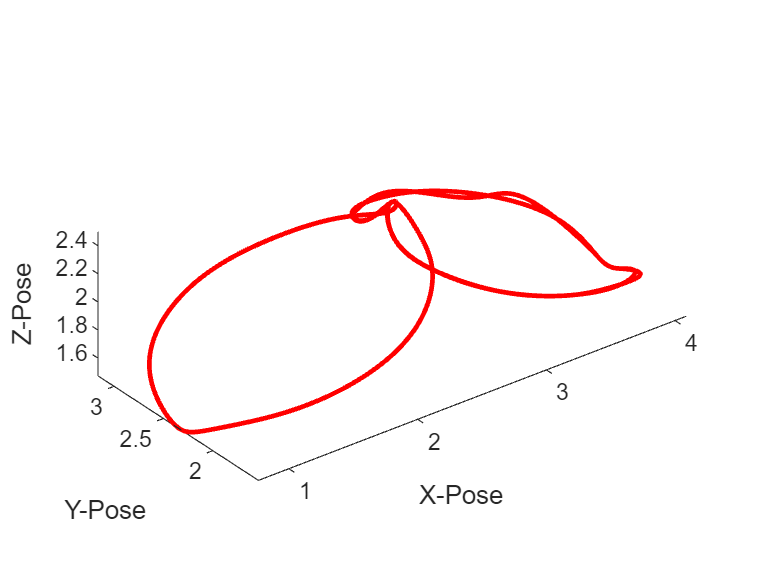

clc
clear all
test = test_ExpAuxiliaryFunctions;
trochoid = test.trochoid(1,"c");

plot3(trochoid(11,:), trochoid(12,:), trochoid(13,:), "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal

%legend('X-positions','Y-positions')

%FO8
clc
clear all
close all
% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
%inf_wpts_zy = [1 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
%inf_wpts_xy = [0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0];

z = [1.5 1 0.5 1 1.5 1 0.5 1 1.5];
a_y = [2 2.5 2 1.5 2 2.5 2 1.5 2];
p_y = [2 2.5 2 1.5 2 1.5 2 2.5 2];
x = [3 2.5 2 2.5 3 3.5 4 3.5 3];

agt_precession_wpts_zy = [z z(:,2:end) z(:,2:end) z(:,2:end);a_y a_y(:,2:end) a_y(:,2:end) a_y(:,2:end)]; 
precession_wpts_zy = [z z(:,2:end) z(:,2:end) z(:,2:end);p_y p_y(:,2:end) p_y(:,2:end) p_y(:,2:end)];

agt_precession_wpts_xy = [x x(:,2:end) x(:,2:end) x(:,2:end);a_y a_y(:,2:end) a_y(:,2:end) a_y(:,2:end)];
precession_wpts_xy = [x x(:,2:end) x(:,2:end) x(:,2:end);p_y p_y(:,2:end) p_y(:,2:end) p_y(:,2:end)];

% tpts = 0:5;
% inf_tpts = 0:sqrt(8):sqrt(8)*8*4;
% numsamples = 100*4;
speed = 1;
r = 0.5;
omega = speed / r; % 1 m/s = 1 rad/s based on v = r*omega
% time_per_eigth = (pi/4)/speed; 
% sample_per_loop = 100;
% time_per_setpt = (time_per_eigth * 8) / sample_per_loop; 

time_per_eigth = (pi/4)/omega; % 0.784
% hz = 100;
hz = 300;
time_per_setpt = 1/hz;
sample_per_loop = (time_per_eigth * 8) / time_per_setpt;  % 2258
sample_per_loop = ceil(sample_per_loop); % only need to change here...
% 1 m/s = (pi/4) / (1 rad/s) = pi/4
% 2 m/s = (pi/4) / (2 rad/s) = pi/8
% 3 m/s = (pi/4) / (3 rad/s) = pi/12
% 4 m/s = (pi/4) / (4 rad/s) = pi/16

circle_tpts = 0:time_per_eigth*2:time_per_eigth*8*8; % intervals @ 1 m/s = 1 rad/s based on v = r*omega

numsamples = sample_per_loop * 8; % 4 times FO8

%[inf_xy,inf_xyd,inf_xydd,inf_xyddd,inf_xydddd,inf_xypp,inf_xytimepoints,inf_xytsamples] = minsnappolytraj(inf_wpts_xy,inf_tpts,numsamples);
%[inf_zy,inf_zyd,inf_zydd,inf_zyddd,inf_zydddd,inf_zypp,inf_zytimepoints,inf_zytsamples] = minsnappolytraj(inf_wpts_zy,inf_tpts,numsamples);

% against precession
[agt_xy,agt_xyd,agt_xydd,agt_xyddd,agt_xydddd,agt_xypp,agt_xytimepoints,agt_xytsamples] = minsnappolytraj(agt_precession_wpts_xy,circle_tpts,numsamples);
[agt_zy,agt_zyd,agt_zydd,agt_zyddd,agt_zydddd,agt_zypp,agt_zytimepoints,agt_zytsamples] = minsnappolytraj(agt_precession_wpts_zy,circle_tpts,numsamples);

% 2 times FO8
agt_final_pos = zeros(3,(sample_per_loop*4)+1);
agt_final_vel = zeros(3,(sample_per_loop*4)+1);
agt_final_acc = zeros(3,(sample_per_loop*4)+1);
agt_final_jer = zeros(3,(sample_per_loop*4)+1);
agt_final_sna = zeros(3,(sample_per_loop*4)+1);

% for v = 1:2
%     agt_final_pose(v,:) = agt_xy(v,101:300);
%     agt_final_vel(v,:) = agt_xyd(v,101:300);
%     agt_final_acc(v,:) = agt_xydd(v,101:300);
%     agt_final_jerk(v,:) = agt_xyddd(v,101:300);
%     agt_final_snap(v,:) = agt_xydddd(v,101:300);
% end

for v = 1:2
    agt_final_pos(v,:) = agt_xy(v,1:(sample_per_loop*4)+1);
    agt_final_vel(v,:) = agt_xyd(v,1:(sample_per_loop*4)+1);
    agt_final_acc(v,:) = agt_xydd(v,1:(sample_per_loop*4)+1);
    agt_final_jer(v,:) = agt_xyddd(v,1:(sample_per_loop*4)+1);
    agt_final_sna(v,:) = agt_xydddd(v,1:(sample_per_loop*4)+1);
end

agt_final_pos(3,:) = agt_zy(1,1:(sample_per_loop*4)+1);
agt_final_vel(3,:) = agt_zyd(1,1:(sample_per_loop*4)+1);
agt_final_acc(3,:) = agt_zydd(1,1:(sample_per_loop*4)+1);
agt_final_jer(3,:) = agt_zyddd(1,1:(sample_per_loop*4)+1);
agt_final_sna(3,:) = agt_zydddd(1,1:(sample_per_loop*4)+1);

a_diff_pos = zeros(2,(sample_per_loop*4)); 
a_diff_vel = zeros(2,(sample_per_loop*4));
a_diff_acc = zeros(2,(sample_per_loop*4));

% used in the later parts
a_diff_jer = zeros(2,(sample_per_loop*4));
a_diff_sna = zeros(2,(sample_per_loop*4));

% disk yawing 
a_diff_rad = zeros(1,(sample_per_loop*4)-1);
a_diff_deg = zeros(1,(sample_per_loop*4)-1); 
a_diff_diff_rad = zeros(1,(sample_per_loop*4)-2);
a_diff_diff_deg = zeros(1,(sample_per_loop*4)-2);

for v = 1:2
    for i = 1:(sample_per_loop*4)
        a_diff_pos(v,i) = agt_final_pos(v,i+1) - agt_final_pos(v,i); 
        a_diff_vel(v,i) = agt_final_vel(v,i+1) - agt_final_vel(v,i); 
        a_diff_acc(v,i) = agt_final_acc(v,i+1) - agt_final_acc(v,i); 
        a_diff_jer(v,i) = agt_final_jer(v,i+1) - agt_final_jer(v,i);
        a_diff_sna(v,i) = agt_final_sna(v,i+1) - agt_final_sna(v,i);
        %diff_deg(v,i) = (direction_deg(v,i+1) - direction_deg(v,i))/time_per_setpt; 
    end
end

a_direction = atan2(a_diff_pos(2,:),a_diff_pos(1,:)); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
a_direction_deg = rad2deg(a_direction);

for i = 1:(sample_per_loop*4)-1
    a_diff_rad(1,i) = (a_direction(1,i+1) - a_direction(1,i))/(time_per_setpt);
    a_diff_deg(1,i) = (a_direction_deg(1,i+1) - a_direction_deg(1,i))/(time_per_setpt);    
end

for i = 1:(sample_per_loop*4)-2
    a_diff_diff_rad(1,i) = (a_diff_rad(1,i+1) - a_diff_rad(1,i))/(time_per_setpt);
    a_diff_diff_deg(1,i) = (a_diff_deg(1,i+1) - a_diff_deg(1,i))/(time_per_setpt);    
end



%plot(tsamples,q);
%plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
%python
%disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

%hold on
%plot(timepoints,wpts,'x')
a_mag = zeros(29,sample_per_loop*4);

a_mag(1,:) = sqrt((a_diff_pos(1,:)).^2 + (a_diff_pos(2,:)).^2); %pos
a_mag(2,:) = sqrt((a_diff_vel(1,:)).^2 + (a_diff_vel(2,:)).^2); %vel
a_mag(3,:) = sqrt((a_diff_acc(1,:)).^2 + (a_diff_acc(2,:)).^2); %acc
a_mag(4,:) = sqrt((a_diff_jer(1,:)).^2 + (a_diff_jer(2,:)).^2); %jer
a_mag(5,:) = sqrt((a_diff_sna(1,:)).^2 + (a_diff_sna(2,:)).^2); %sna

a_mag(6,:) = a_direction; %direction
a_mag(7,1) = time_per_setpt; %update rate
a_mag(8,1:9) = x; 
a_mag(9,:) = a_direction_deg; %direction
a_mag(10,1) = sample_per_loop;
a_mag(10,2) = (sample_per_loop*2); % number of points ran in this function
a_mag(11,:) = agt_final_pos(1,1:sample_per_loop*4); % x
a_mag(12,:) = agt_final_pos(2,1:sample_per_loop*4); % y
a_mag(13,:) = agt_final_pos(3,1:sample_per_loop*4); % z
a_mag(14,:) = agt_final_vel(1,1:sample_per_loop*4); % x
a_mag(15,:) = agt_final_vel(2,1:sample_per_loop*4); % y
a_mag(16,:) = agt_final_vel(3,1:sample_per_loop*4); % z
a_mag(17,:) = agt_final_acc(1,1:sample_per_loop*4); % x
a_mag(18,:) = agt_final_acc(2,1:sample_per_loop*4); % y
a_mag(19,:) = agt_final_acc(3,1:sample_per_loop*4); % z
a_mag(20,:) = agt_final_jer(1,1:sample_per_loop*4); % x
a_mag(21,:) = agt_final_jer(2,1:sample_per_loop*4); % y
a_mag(22,:) = agt_final_jer(3,1:sample_per_loop*4); % z
a_mag(23,:) = agt_final_sna(1,1:sample_per_loop*4); % x
a_mag(24,:) = agt_final_sna(2,1:sample_per_loop*4); % y
a_mag(25,:) = agt_final_sna(3,1:sample_per_loop*4); % z
a_mag(26,1:(sample_per_loop*4)-1) = a_diff_rad(1,:); % rad/s
a_mag(27,1:(sample_per_loop*4)-1) = a_diff_deg(1,:); % deg/s
a_mag(28,1:(sample_per_loop*4)-2) = a_diff_diff_rad(1,:); % rad/s/s
a_mag(29,1:(sample_per_loop*4)-2) = a_diff_diff_deg(1,:); % deg/s/s

figure(1)
% subplot(3,1,1) 
% plot(mag(11,:), mag(12,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(a_mag(11,1:sample_per_loop*2), a_mag(12,1:sample_per_loop*2))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
title('yaw rate against precession')
% grid
% 
% subplot(3,1,3)

plot3(a_mag(11,:), a_mag(12,:), a_mag(13,:), "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
%legend('X-positions','Y-positions')




% precession
[p_xy,p_xyd,p_xydd,p_xyddd,p_xydddd,p_xypp,p_xytimepoints,p_xytsamples] = minsnappolytraj(precession_wpts_xy,circle_tpts,numsamples);
[p_zy,p_zyd,p_zydd,p_zyddd,p_zydddd,p_zypp,p_zytimepoints,p_zytsamples] = minsnappolytraj(precession_wpts_zy,circle_tpts,numsamples);

% 2 times FO8
p_final_pos = zeros(3,(sample_per_loop*4)+1);
p_final_vel = zeros(3,(sample_per_loop*4)+1);
p_final_acc = zeros(3,(sample_per_loop*4)+1);
p_final_jer = zeros(3,(sample_per_loop*4)+1);
p_final_sna = zeros(3,(sample_per_loop*4)+1);

% for v = 1:2
%     agt_final_pose(v,:) = agt_xy(v,101:300);
%     agt_final_vel(v,:) = agt_xyd(v,101:300);
%     agt_final_acc(v,:) = agt_xydd(v,101:300);
%     agt_final_jerk(v,:) = agt_xyddd(v,101:300);
%     agt_final_snap(v,:) = agt_xydddd(v,101:300);
% end

for v = 1:2
    p_final_pos(v,:) = p_xy(v,1:(sample_per_loop*4)+1);
    p_final_vel(v,:) = p_xyd(v,1:(sample_per_loop*4)+1);
    p_final_acc(v,:) = p_xydd(v,1:(sample_per_loop*4)+1);
    p_final_jer(v,:) = p_xyddd(v,1:(sample_per_loop*4)+1);
    p_final_sna(v,:) = p_xydddd(v,1:(sample_per_loop*4)+1);
end

p_final_pos(3,:) = p_zy(1,1:(sample_per_loop*4)+1);
p_final_vel(3,:) = p_zyd(1,1:(sample_per_loop*4)+1);
p_final_acc(3,:) = p_zydd(1,1:(sample_per_loop*4)+1);
p_final_jer(3,:) = p_zyddd(1,1:(sample_per_loop*4)+1);
p_final_sna(3,:) = p_zydddd(1,1:(sample_per_loop*4)+1);

p_diff_pos = zeros(2,(sample_per_loop*4)); 
p_diff_vel = zeros(2,(sample_per_loop*4));
p_diff_acc = zeros(2,(sample_per_loop*4));

% used in the later parts
p_diff_jer = zeros(2,(sample_per_loop*4));
p_diff_sna = zeros(2,(sample_per_loop*4));

% disk yawing 
p_diff_rad = zeros(1,(sample_per_loop*4)-1);
p_diff_deg = zeros(1,(sample_per_loop*4)-1); 
p_diff_diff_rad = zeros(1,(sample_per_loop*4)-2);
p_diff_diff_deg = zeros(1,(sample_per_loop*4)-2);

for v = 1:2
    for i = 1:(sample_per_loop*4)
        p_diff_pos(v,i) = p_final_pos(v,i+1) - p_final_pos(v,i); 
        p_diff_vel(v,i) = p_final_vel(v,i+1) - p_final_vel(v,i); 
        p_diff_acc(v,i) = p_final_acc(v,i+1) - p_final_acc(v,i); 
        p_diff_jer(v,i) = p_final_jer(v,i+1) - p_final_jer(v,i);
        p_diff_sna(v,i) = p_final_sna(v,i+1) - p_final_sna(v,i);
        %diff_deg(v,i) = (direction_deg(v,i+1) - direction_deg(v,i))/time_per_setpt; 
    end
end

p_direction = atan2(p_diff_pos(2,:),p_diff_pos(1,:)); % this atan2 doesnt describe the angle, rather it describes where the adjacent axis would point 
p_direction_deg = rad2deg(p_direction);

for i = 1:(sample_per_loop*4)-1
    p_diff_rad(1,i) = (p_direction(1,i+1) - p_direction(1,i))/(time_per_setpt);
    p_diff_deg(1,i) = (p_direction_deg(1,i+1) - p_direction_deg(1,i))/(time_per_setpt);    
end

for i = 1:(sample_per_loop*4)-2
    p_diff_diff_rad(1,i) = (p_diff_rad(1,i+1) - p_diff_rad(1,i))/(time_per_setpt);
    p_diff_diff_deg(1,i) = (p_diff_deg(1,i+1) - p_diff_deg(1,i))/(time_per_setpt);    
end



%plot(tsamples,q);
%plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
%python
%disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

%hold on
%plot(timepoints,wpts,'x')
p_mag = zeros(29,sample_per_loop*4);

p_mag(1,:) = sqrt((p_diff_pos(1,:)).^2 + (p_diff_pos(2,:)).^2); %pos
p_mag(2,:) = sqrt((p_diff_vel(1,:)).^2 + (p_diff_vel(2,:)).^2); %vel
p_mag(3,:) = sqrt((p_diff_acc(1,:)).^2 + (p_diff_acc(2,:)).^2); %acc
p_mag(4,:) = sqrt((p_diff_jer(1,:)).^2 + (p_diff_jer(2,:)).^2); %jer
p_mag(5,:) = sqrt((p_diff_sna(1,:)).^2 + (p_diff_sna(2,:)).^2); %sna

p_mag(6,:) = p_direction; %direction
p_mag(7,1) = time_per_setpt; %update rate
p_mag(8,1:9) = x; 
p_mag(9,:) = p_direction_deg; %direction
p_mag(10,1) = sample_per_loop;
p_mag(10,2) = (sample_per_loop*2); % number of points ran in this function
p_mag(11,:) = p_final_pos(1,1:sample_per_loop*4); % x
p_mag(12,:) = p_final_pos(2,1:sample_per_loop*4); % y
p_mag(13,:) = p_final_pos(3,1:sample_per_loop*4); % z
p_mag(14,:) = p_final_vel(1,1:sample_per_loop*4); % x
p_mag(15,:) = p_final_vel(2,1:sample_per_loop*4); % y
p_mag(16,:) = p_final_vel(3,1:sample_per_loop*4); % z
p_mag(17,:) = p_final_acc(1,1:sample_per_loop*4); % x
p_mag(18,:) = p_final_acc(2,1:sample_per_loop*4); % y
p_mag(19,:) = p_final_acc(3,1:sample_per_loop*4); % z
p_mag(20,:) = p_final_jer(1,1:sample_per_loop*4); % x
p_mag(21,:) = p_final_jer(2,1:sample_per_loop*4); % y
p_mag(22,:) = p_final_jer(3,1:sample_per_loop*4); % z
p_mag(23,:) = p_final_sna(1,1:sample_per_loop*4); % x
p_mag(24,:) = p_final_sna(2,1:sample_per_loop*4); % y
p_mag(25,:) = p_final_sna(3,1:sample_per_loop*4); % z
p_mag(26,1:(sample_per_loop*4)-1) = p_diff_rad(1,:); % rad/s
p_mag(27,1:(sample_per_loop*4)-1) = p_diff_deg(1,:); % deg/s
p_mag(28,1:(sample_per_loop*4)-2) = p_diff_diff_rad(1,:); % rad/s/s
p_mag(29,1:(sample_per_loop*4)-2) = p_diff_diff_deg(1,:); % deg/s/s

figure(1)
% subplot(3,1,1) 
% plot(mag(11,:), mag(12,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(p_mag(11,1:1000), p_mag(12,1:1000))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
title('yaw rate with precession')
% grid
% 
% subplot(3,1,3)

plot3(p_mag(11,:), p_mag(12,:), p_mag(13,:), "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
%legend('X-positions','Y-positions')

%straight line
clc
clear all
close all
r=1; % radius
[c,x,y] = circle(-2,2,r);
x = x*-1;
y = x;
mm = sqrt(x.^2 + y.^2)
z = [1,1.5,2,1.5,1,1.5,2,1.5,1]
% y = y*-1;
disp (size(x));
disp ((x));
disp ((y));


% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
%wpts_zy = [0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
circle_wpts_xy = [mm mm(:,2:end) mm(:,2:end) mm(:,2:end); z z(:,2:end) z(:,2:end) z(:,2:end)]; % repeats for 4 times to ensure smoothness but we only take the middle points
% tpts = 0:5;

speed = 1; % 1 m/s = 1 rad/s based on v = r*omega 
sample_per_loop = 100;
time_per_setpt = ((sqrt(2) * 4) / sample_per_loop)/speed
total_time = time_per_setpt * 100;
 

% 1 m/s = (pi/4) / (1 rad/s) = pi/4
% 2 m/s = (pi/4) / (2 rad/s) = pi/8
% 3 m/s = (pi/4) / (3 rad/s) = pi/12
% 4 m/s = (pi/4) / (4 rad/s) = pi/16

circle_tpts = 0:total_time/8:total_time*4 % intervals @ 1 m/s = 1 rad/s based on v = r*omega


numsamples = sample_per_loop * 4;

[circle_xy,circle_xyd,circle_xydd,circle_xyddd,circle_xydddd,circle_xypp,circle_xytimepoints,circle_xytsamples] = minsnappolytraj(circle_wpts_xy,circle_tpts,numsamples);
%[zy,zyd,zydd,zyddd,zydddd,zypp,zytimepoints,zytsamples] = minsnappolytraj(wpts_zy,tpts,numsamples);

circle_final_pose = zeros(2,201);
t_final_vel = zeros(2,201);
t_final_acc = zeros(2,201);
circle_final_jerk = zeros(2,201);
circle_final_snap = zeros(2,201);

% final_z_pose = zy(1,101:300);
% final_z_vel = zyd(1,101:300);
% final_z_acc = zydd(1,101:300);
% final_z_jerk = zyddd(1,101:300);
% final_z_snap = zydddd(1,101:300);

for v = 1:2
    circle_final_pose(v,:) = circle_xy(v,101:301);
    t_final_vel(v,:) = circle_xyd(v,101:301);
    t_final_acc(v,:) = circle_xydd(v,101:301);
    circle_final_jerk(v,:) = circle_xyddd(v,101:301);
    circle_final_snap(v,:) = circle_xydddd(v,101:301);
end

% because the above solution starts from the same point but moves in a
% clockwise fashion as compared to what I wanted which was anti-clockwise
% from the same starting pt

invert_pos = zeros(2,201);
invert_pos(2,:) = (circle_final_pose(2,:));
invert_pos(1,:) = flip(circle_final_pose(1,:));

invert_vel = zeros(2,201);
invert_vel(2,:) = (t_final_vel(2,:));
invert_vel(1,:) = (t_final_vel(1,:));

invert_acc = zeros(2,201);
invert_acc(2,:) = (t_final_acc(2,:));
invert_acc(1,:) = (t_final_acc(1,:));

invert_jer = zeros(2,201);
invert_jer(2,:) = (circle_final_jerk(2,:));
invert_jer(1,:) = (circle_final_jerk(1,:));

invert_sna = zeros(2,201);
invert_sna(2,:) = (circle_final_snap(2,:));
invert_sna(1,:) = (circle_final_snap(1,:));

diff_pos = zeros(2,200); 
diff_vel = zeros(2,200);
diff_acc = zeros(2,200);

% used in the later parts
diff_jer = zeros(2,200);
diff_sna = zeros(2,200);

for v = 1:2
    for i = 1:200
        diff_pos(v,i) = invert_pos(v,i+1) - invert_pos(v,i); 
        diff_vel(v,i) = invert_vel(v,i+1) - invert_vel(v,i); 
        diff_acc(v,i) = invert_acc(v,i+1) - invert_acc(v,i); 
        diff_jer(v,i) = invert_jer(v,i+1) - invert_jer(v,i); 
        diff_sna(v,i) = invert_sna(v,i+1) - invert_sna(v,i); 
    end
end

s_mag = zeros(5,200);

s_mag(1,:) = sqrt((diff_pos(1,:)).^2 + (diff_pos(2,:)).^2);
s_mag(2,:) = sqrt((diff_vel(1,:)).^2 + (diff_vel(2,:)).^2);
s_mag(3,:) = sqrt((diff_acc(1,:)).^2 + (diff_acc(2,:)).^2);
s_mag(4,:) = sqrt((diff_jer(1,:)).^2 + (diff_jer(2,:)).^2);
s_mag(5,:) = sqrt((diff_sna(1,:)).^2 + (diff_sna(2,:)).^2);

direction = atan2(diff_pos(2,:),diff_pos(1,:));
direction_deg = rad2deg(direction);



% direction = atan2(circle_final_pose(1,:),circle_final_pose(2,:));

% direction_deg = rad2deg(atan2(diff_y(:,26:50),diff_x(:,26:50)));
% direction = atan2(diff_y(:,1:25),diff_x(:,1:25));
% polarplot(direction,mag(:,1:25));


polarplot(direction,s_mag(1,:));


% plot(tsamples,q);
% plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
% python
% disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

% hold on
% plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(circle_final_pose(1,:), circle_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
% grid
% 
% subplot(3,1,3)
z = zeros([size(circle_final_pose(1,:))]);
plot3(circle_final_pose(1,:), z, circle_final_pose(2,:), "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
% %legend('X-positions','Y-positions')


%CIRCLE
clc
clear all
close all
r=1; % radius
[c,x,y] = circle(-2,2,r);
x = x*-1;
y = x;
mm = sqrt(x.^2 + y.^2)
z = [1,1.25,1.5,1.75,2,1.75,1.5,1.25,1]
% y = y*-1;
disp (size(x));
disp ((x));
disp ((y));


% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
%wpts_zy = [0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
circle_wpts_xy = [x x(:,2:end) x(:,2:end) x(:,2:end); y y(:,2:end) y(:,2:end) y(:,2:end)]; % repeats for 4 times to ensure smoothness but we only take the middle points
% tpts = 0:5;

speed = 1; % 1 m/s = 1 rad/s based on v = r*omega
time_per_eigth = (pi/4)/speed; 
sample_per_loop = 100;

% 1 m/s = (pi/4) / (1 rad/s) = pi/4
% 2 m/s = (pi/4) / (2 rad/s) = pi/8
% 3 m/s = (pi/4) / (3 rad/s) = pi/12
% 4 m/s = (pi/4) / (4 rad/s) = pi/16

circle_tpts = 0:time_per_eigth:time_per_eigth*8*4; % intervals @ 1 m/s = 1 rad/s based on v = r*omega

numsamples = sample_per_loop * 4;

[circle_xy,circle_xyd,circle_xydd,circle_xyddd,circle_xydddd,circle_xypp,circle_xytimepoints,circle_xytsamples] = minsnappolytraj(circle_wpts_xy,circle_tpts,numsamples);
%[zy,zyd,zydd,zyddd,zydddd,zypp,zytimepoints,zytsamples] = minsnappolytraj(wpts_zy,tpts,numsamples);

circle_final_pose = zeros(2,201);
t_final_vel = zeros(2,201);
t_final_acc = zeros(2,201);
circle_final_jerk = zeros(2,201);
circle_final_snap = zeros(2,201);

% final_z_pose = zy(1,101:300);
% final_z_vel = zyd(1,101:300);
% final_z_acc = zydd(1,101:300);
% final_z_jerk = zyddd(1,101:300);
% final_z_snap = zydddd(1,101:300);

for v = 1:2
    circle_final_pose(v,:) = circle_xy(v,101:301);
    t_final_vel(v,:) = circle_xyd(v,101:301);
    t_final_acc(v,:) = circle_xydd(v,101:301);
    circle_final_jerk(v,:) = circle_xyddd(v,101:301);
    circle_final_snap(v,:) = circle_xydddd(v,101:301);
end

% because the above solution starts from the same point but moves in a
% clockwise fashion as compared to what I wanted which was anti-clockwise
% from the same starting pt

invert_pos = zeros(2,201);
invert_pos(2,:) = (circle_final_pose(2,:));
invert_pos(1,:) = flip(circle_final_pose(1,:));

invert_vel = zeros(2,201);
invert_vel(2,:) = (t_final_vel(2,:));
invert_vel(1,:) = (t_final_vel(1,:));

invert_acc = zeros(2,201);
invert_acc(2,:) = (t_final_acc(2,:));
invert_acc(1,:) = (t_final_acc(1,:));

invert_jer = zeros(2,201);
invert_jer(2,:) = (circle_final_jerk(2,:));
invert_jer(1,:) = (circle_final_jerk(1,:));

invert_sna = zeros(2,201);
invert_sna(2,:) = (circle_final_snap(2,:));
invert_sna(1,:) = (circle_final_snap(1,:));

diff_pos = zeros(2,200); 
diff_vel = zeros(2,200);
diff_acc = zeros(2,200);

% used in the later parts
diff_jer = zeros(2,200);
diff_sna = zeros(2,200);

for v = 1:2
    for i = 1:200
        diff_pos(v,i) = invert_pos(v,i+1) - invert_pos(v,i); 
        diff_vel(v,i) = invert_vel(v,i+1) - invert_vel(v,i); 
        diff_acc(v,i) = invert_acc(v,i+1) - invert_acc(v,i); 
        diff_jer(v,i) = invert_jer(v,i+1) - invert_jer(v,i); 
        diff_sna(v,i) = invert_sna(v,i+1) - invert_sna(v,i); 
    end
end

c_mag = zeros(5,200);

c_mag(1,:) = sqrt((diff_pos(1,:)).^2 + (diff_pos(2,:)).^2);
c_mag(2,:) = sqrt((diff_vel(1,:)).^2 + (diff_vel(2,:)).^2);
c_mag(3,:) = sqrt((diff_acc(1,:)).^2 + (diff_acc(2,:)).^2);
c_mag(4,:) = sqrt((diff_jer(1,:)).^2 + (diff_jer(2,:)).^2);
c_mag(5,:) = sqrt((diff_sna(1,:)).^2 + (diff_sna(2,:)).^2);

direction = atan2(diff_pos(2,:),diff_pos(1,:));
direction_deg = rad2deg(direction);



% direction = atan2(circle_final_pose(1,:),circle_final_pose(2,:));

% direction_deg = rad2deg(atan2(diff_y(:,26:50),diff_x(:,26:50)));
% direction = atan2(diff_y(:,1:25),diff_x(:,1:25));
% polarplot(direction,mag(:,1:25));


polarplot(direction,c_mag(1,:));


% plot(tsamples,q);
% plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
% python
% disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

% hold on
% plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(circle_final_pose(1,:), circle_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
% grid
% 
% subplot(3,1,3)
z = ones([size(circle_final_pose(1,:))]);
plot3(circle_final_pose(1,:), circle_final_pose(2,:), z, "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
% %legend('X-positions','Y-positions')

% testing the classes

% aux = ExpAuxiliaryFunctions;
% y = aux.quadrant_output(-2.356)
% C1 = aux.circle_setpoints_anti_cw(1,2,2,1)
% C = aux.circle_setpoints_cw(1,-2,2,1)
clc
clear all
test = test_ExpAuxiliaryFunctions;
hz = 60;
C3 = test.circle_setpoints_anti_cw(1,2.0,2.0,0.5,hz,"c"); % comparing against this, matlab update rate is at 60 hz
diff_flat = zeros(10,C3(10,2));
col_size = C3(10,2)

col_size = 378

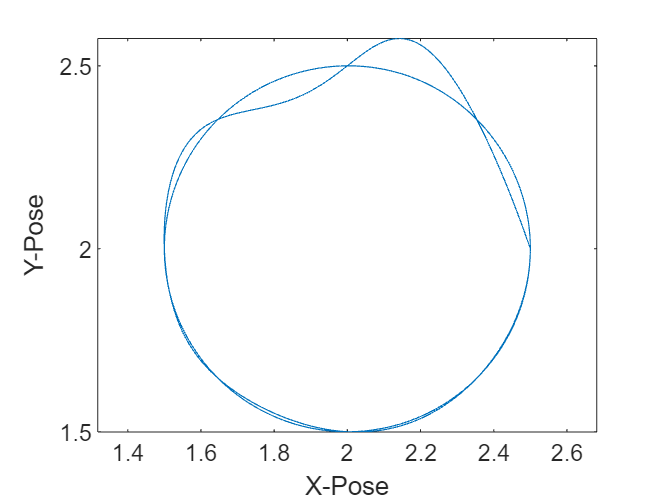

%C3 = flip(C3,2); % circle goes the other way, proved that the rotation direction can improve or impede the linear acceleration
%actuation_angles = zeros(178,3,361); % the last axis is the layer
actuation_angles = zeros(360,179);
i = 2;
c = 1;
%p = -180;

for p = -180:179
    k = deg2rad(p); % desired heading
    actuation_angles(c,1) = p;
    for v = -180:180
        a = deg2rad(v); % azimuth
        quad = test.quadrant_output(k);
        flap = abs(test.flap_output(a,quad,k,-1));
        if flap(:,1) > 0
            actuation_angles(c,i) = v; % azimuth w abs(flap) > 1
            i = i+1;
        end
    end 
    i = 2;
    c = c+1;
end


% diff flat is defined on top
drag = [0,0,0];
pitch = 25.61; % degrees
rotation_dir = -1; 
% 1 represents ccw which means z vector faces up  
% -1 represents cw which means z vector faces down  
for i = 1:col_size
    vel = [C3(14,i),C3(15,i),C3(16,i)];
    acc = [C3(17,i),C3(18,i),C3(19,i)];
    jer = [C3(20,i),C3(21,i),C3(22,i)];
    sna = [C3(23,i),C3(24,i),C3(25,i)];
    diff_flat(:,i) = transpose(test.diff_flat(pitch,drag,vel,acc,jer,sna,"circle",rotation_dir));
end

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 

plot(C3(11,:), C3(12,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal

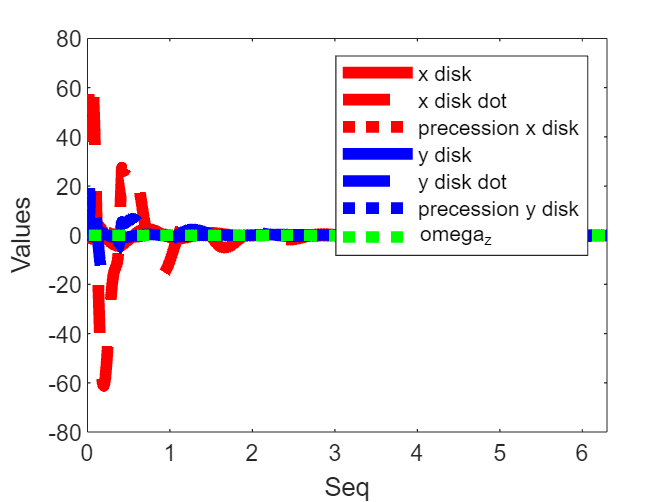




A = C3(26,:); % rad/s
threshold = [1 99];
desired_precession = transpose(rmoutliers(A,"percentiles",threshold));
p_size = size(desired_precession);
desired_acc = transpose(C3(18,1:p_size(1,1))); % y acc
%fprintf('Desired precession (%d) vs desired acc (%d)', B, counter_actl);
%plot(1:p_size(1,1),desired_precession)
% hold on
% plot(1:p_size(1,1),desired_acc,'Color','red')
%xlabel('Seq')
%ylabel('Values')
% legend('desired precession','desired acc')
% hold off

% f = fitlm(desired_acc,desired_precession) % acc precession function
% linear_p = 0.0014513 + 114.62*(desired_acc);
% plot(desired_acc,linear_p);


plot((1:col_size)/hz,diff_flat(1,:),'Color','red','linewidth',5)
hold on
plot((1:col_size)/hz,diff_flat(3,:),'Color','red','lineStyle','--','linewidth',5)
plot((1:col_size)/hz,diff_flat(5,:),'Color','red','lineStyle',':','linewidth',5)
plot((1:col_size)/hz,diff_flat(2,:),'Color','blue','linewidth',5)
plot((1:col_size)/hz,diff_flat(4,:),'Color','blue','lineStyle','--','linewidth',5)
plot((1:col_size)/hz,diff_flat(6,:),'Color','blue','lineStyle',':','linewidth',5)
plot((1:col_size)/hz,diff_flat(8,:)/100,'Color','green','lineStyle',':','linewidth',5)
%plot(1:1886,diff_flat(7,:),'Color','green','linewidth',5)
xlabel('Seq')
ylabel('Values')
legend('x disk','x disk dot','precession x disk','y disk','y disk dot','precession y disk','omega_z')
hold off


current_location = [2.5,2.0,1.0];
desired_location = [2.0,1.5,1.0];
kp = 0.5;
error = kp*(desired_location - current_location);
mea_euler = [0,0,0];
test.test_attitude(mea_euler,error)

ans =     0.5000   -0.5000


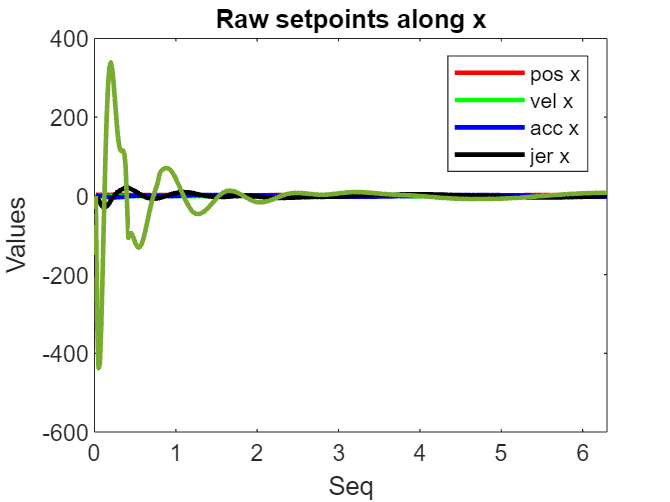





pos_x = C3(11,:);
pos_y = C3(12,:);
vel_x = C3(14,:);
vel_y = C3(15,:);
acc_x = C3(17,:);
acc_y = C3(18,:);
jer_x = C3(20,:);
jer_y = C3(21,:);
sna_x = C3(23,:);
sna_y = C3(24,:);

gyro_x = diff_flat(5,:);
gyro_y = diff_flat(6,:);
gyro_x_dot = diff_flat(7,:);
gyro_y_dot = diff_flat(8,:);
total_gyro = gyro_x+gyro_y;


plot((1:col_size)/hz,pos_x,'Color','red','linewidth',2)
hold on
plot((1:col_size)/hz,vel_x,'Color','green','linewidth',2)
plot((1:col_size)/hz,acc_x,'Color','blue','linewidth',2)
plot((1:col_size)/hz,jer_x,'Color','black','linewidth',2)
plot((1:col_size)/hz,sna_x,'linewidth',2)
xlabel('Seq')
ylabel('Values')
title('Raw setpoints along x')
legend('pos x','vel x','acc x','jer x')
hold off

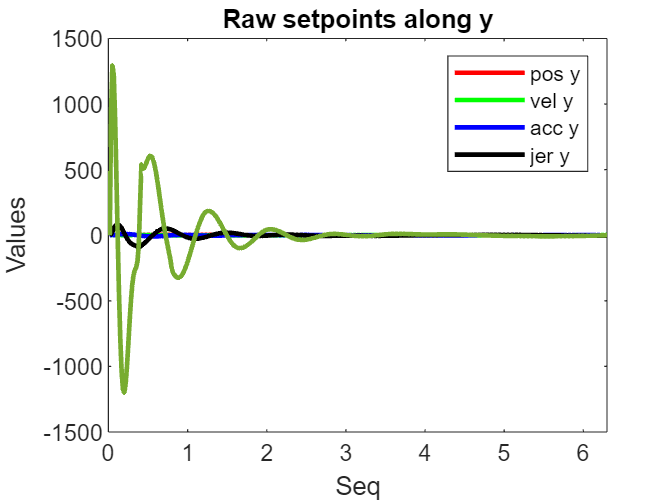



plot((1:col_size)/hz,pos_y,'Color','red','linewidth',2)
hold on
plot((1:col_size)/hz,vel_y,'Color','green','linewidth',2)
plot((1:col_size)/hz,acc_y,'Color','blue','linewidth',2)
plot((1:col_size)/hz,jer_y,'Color','black','linewidth',2)
plot((1:col_size)/hz,sna_y,'linewidth',2)
xlabel('Seq')
ylabel('Values')
title('Raw setpoints along y')
legend('pos y','vel y','acc y','jer y')
hold off

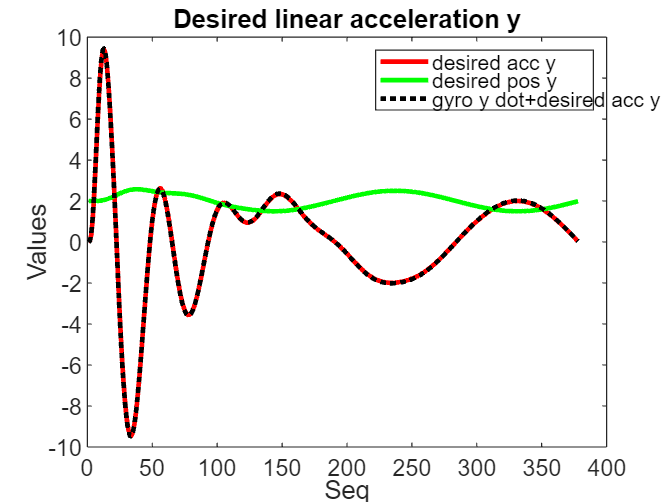

% xlim([250,2100])

plot(1:col_size,acc_y,'Color','red','linewidth',2)
%plot(1:col_size,gyro_x+gyro_y,'Color','red','linewidth',2)
% dp = transpose(desired_precession);
% plot(1:p_size(1,1),dp(1:p_size(1,1)),'Color','red','linewidth',2)
hold on
plot(1:col_size,pos_y,'Color','green','linewidth',2)
%plot(1:col_size,acc_y,'Color','blue','linewidth',2)
%plot(1:p_size(1,1),dp(1:p_size(1,1)) - total_gyro(1:p_size(1,1)),'Color','black','lineStyle',':','linewidth',2)
plot(1:col_size,gyro_y_dot+acc_y,'Color','black','lineStyle',':','linewidth',2)
% plot(1:100,desired_precession-(total_gyro(1:1:p_size(1,1))),'Color','blue','linewidth',2)
xlabel('Seq')
ylabel('Values')
title('Desired linear acceleration y')
legend('desired acc y','desired pos y','gyro y dot+desired acc y')
% legend('dp','dp+gyro')
% legend('gyro_x+gyro_y','pref-(gyro_x+gyro_y)')
hold off

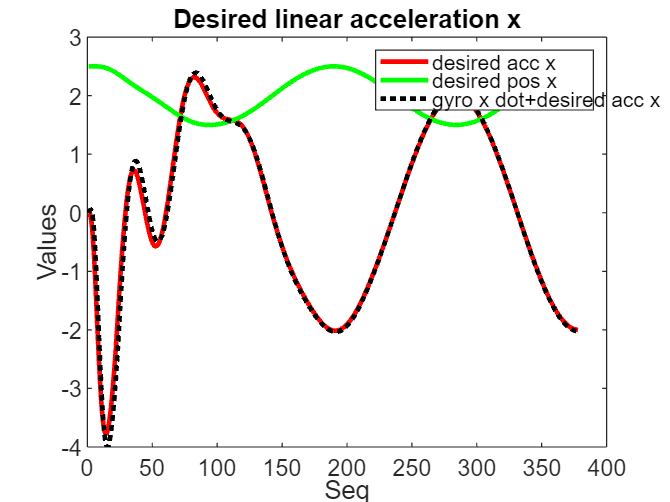

%ylim([1.9 2.15]) % compute error to say residual gyroscopic effects are negligible 


plot(1:col_size,acc_x,'Color','red','linewidth',2)
hold on
plot(1:col_size,pos_x,'Color','green','linewidth',2)
plot(1:col_size,gyro_x_dot+acc_x,'Color','black','lineStyle',':','linewidth',2)
xlabel('Seq')
ylabel('Values')
title('Desired linear acceleration x')
legend('desired acc x','desired pos x','gyro x dot+desired acc x')
hold off



theta = 20;
phi = -20; % roll
theta = 2; % pitch 
v = [4000;-1000;-1440];

W = [ 1,  0,        -sin(theta);
          0,  cos(phi),  cos(theta)*sin(phi);
          0, -sin(phi),  cos(theta)*cos(phi) ];


clc
clear all
close all
[c,x,y] = circle(0,0,1);
disp (size(x));

% Specify waypoints, times of arrival, and sampling rate. 
wp = [0 0 0; 2 -2 0; 4 0 0; 6 2 0; 8 0 0; 6 -2 0; 4 0 0; 2 2 0; 0 0 0];
toa = sqrt(8)*(0:size(wp,1)-1).'
vel = [0 0 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 0 0 0];
Fs = 100; % resolution

% Create trajectory. 
traj = waypointTrajectory(wp, toa, SampleRate=Fs, ReferenceFrame='ENU')
disp (traj.Velocities);
% Get position.
t = 0:1/Fs:traj.TimeOfArrival(end);
pos = lookupPose(traj, t);
size(pos)

figure(1)
subplot(2,1,1) 
plot(t,pos(:,2))
xlabel('t');
ylabel('Y-Positions');
subplot(2,1,2) 
plot(pos(:,1),pos(:,2))
xlabel('X-Pose')
ylabel('Y-Pose')

function [overall,xunit,yunit] = circle(x,y,r)
% hold on
x_origin = x;
y_origin = y;
radius = r;
%th = 0:pi/50:2*pi; % 100 pts
th = 0:pi/4:2*pi; % 8 pts
xunit = radius * cos(th) + x_origin;
yunit = radius * sin(th) + y_origin;
z = ones([size(xunit)]);
overall = plot3(xunit, yunit, z, "red",'LineWidth',5);
xlabel('X')
ylabel('Y')
ylabel('Z')
%axis equal
% hold off
end


